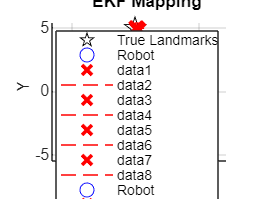

clear; clc; close all;

% --- PARAMETERS ---
n_landmarks = 4;
Q = diag([0.1, deg2rad(5)]).^2;  % Measurement noise: range (m), bearing (rad)
R = diag([0.5, 0.5]).^2;         % Initial landmark uncertainty

% True landmark positions (for sim only)
true_landmarks = [5 5; 10 0; 7 -5; 2 -3];

% Robot known trajectory (x, y, theta)
robot_path = [0 0 0;
              1 0 0;
              2 0 0;
              2 1 pi/2;
              2 2 pi/2;
              1 2 pi;
              0 2 0];

% Initial state
mu = [];           % Landmark positions [x1; y1; x2; y2; ...]
Sigma = [];        % Covariance matrix

% Data association (for simplicity, assume perfect association)
observed_ids = {}; % Cell array for storing observed landmark IDs at each step

figure;
hold on; grid on; axis equal;
xlabel('X'); ylabel('Y');
plot(true_landmarks(:,1), true_landmarks(:,2), 'kp', 'MarkerSize', 12, 'DisplayName','True Landmarks');

% --- SIMULATION LOOP ---
for t = 1:size(robot_path, 1)
    pose = robot_path(t, :); % [x, y, theta]
    [z, ids] = simulate_measurements(pose, true_landmarks, Q);
    observed_ids{t} = ids;

    for i = 1:length(ids)
        id = ids(i);
        z_i = z(:, i);

        idx = 2*id-1; % Index in state vector

        if length(mu) < idx + 1
            [mu, Sigma] = initialize_landmark(mu, Sigma, pose, z_i, R, id);
        else
            [mu, Sigma] = ekf_update(mu, Sigma, pose, z_i, Q, id);
        end
    end

    plot_map(mu, Sigma, pose, t);
    pause(0.5);
end

title('EKF Mapping')